# B3シミュレーション

## 送信側

clear;
clc;

%データレートよりもサンプリング周波数の方が十分大きくなければならない
Fs = 10000 %サンプリング周波数[Hz]

Fs = 10000

Ts = 1/Fs  %サンプリング周期[s]

Ts = 1.0000e-04

Fd = 10    %データレート[Hz]

Fd = 10

Td = 1/Fd  %データの周期（ナイキスト周期）[s]

Td = 0.1000

Fc = 100   %搬送波周波数[Hz]

Fc = 100

A  = 3     %振幅

A = 3

TXD = [0 0 1 1 0 0 1 0 0 1 0]  %送信データ

TXD =      0     0     1     1     0     0     1     0     0     1     0


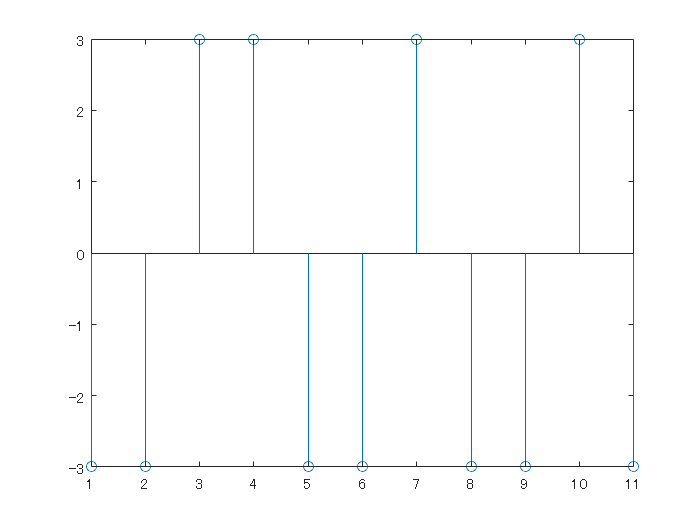

t  = 0:Ts:(numel(TXD)-1)*Td;   %離散時間[s]

%信号空間ダイアグラムへのマッピング
BPSK(TXD==0) = -A;
BPSK(TXD==1) = A;
stem(BPSK)

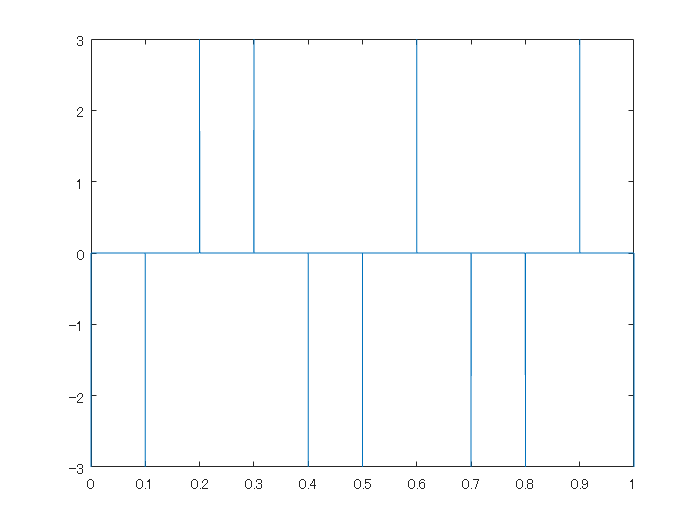


%インパルス列作成
i = 1;
impulse = zeros(1,numel(t));
for data = BPSK
    impulse(i) = data;
    i = i + Fs/Fd;
end
plot(t,impulse);

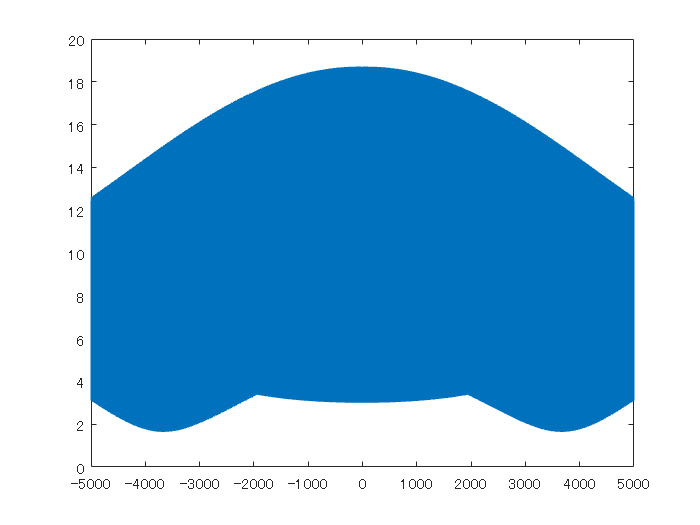

f_impulse = linspace(-Fs/2,Fs/2,numel(t));
impulse_fft = fft(impulse);
plot(f_impulse,abs(fftshift(impulse_fft)));

%フィルタのインパルス応答を計算
k = 50;%フィルタインパルス応答の打ち切り時間調整
tf = -Td*k:Ts:Td*k-Ts; %フィルタインパルス応答の時間列
h = (1/Td).*sinc(tf/Td);
numel(h)

ans = 100000

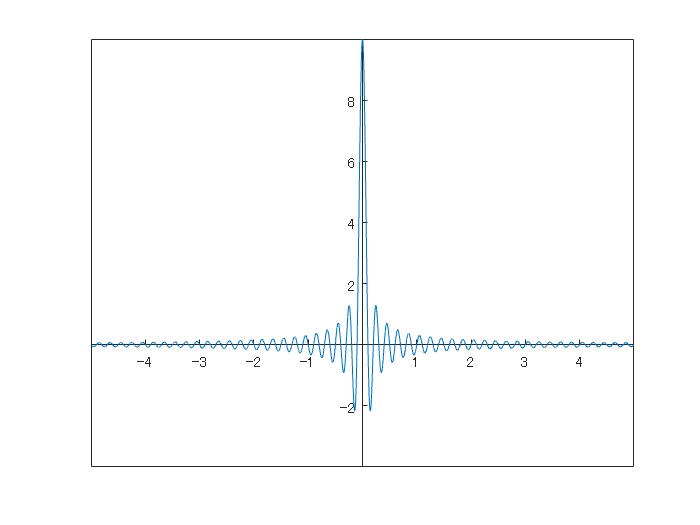


plot(tf,h);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

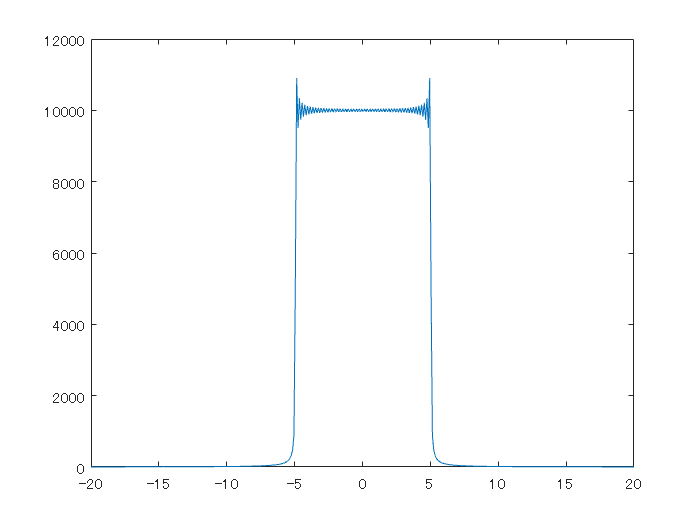

h_fft = fft(h);

f_h = linspace(-Fs/2,Fs/2,numel(tf));
plot(f_h,abs(fftshift(h_fft)));
xlim([-2/Td 2/Td]);

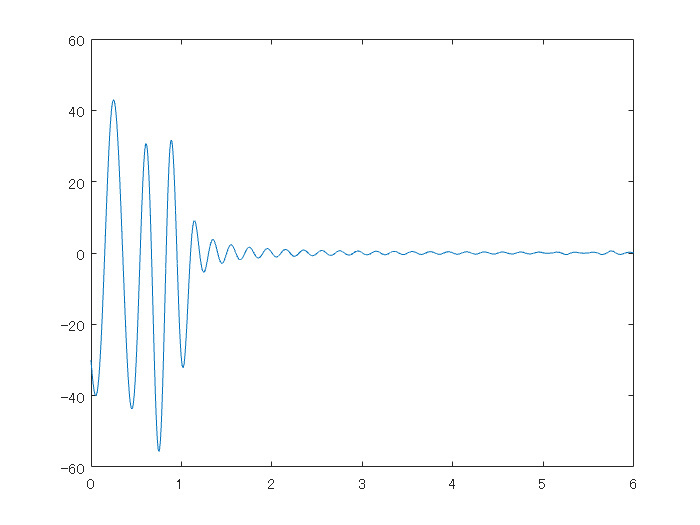


%インパルス列をフィルタに通過させる
impulse_LPF = conv(impulse,h);
delay = numel(h)/2; %フィルタの遅延量
impulse_LPF(1:delay) = [];
t_LPF = 0:Ts:numel(impulse_LPF)*Ts-Ts;
plot(t_LPF,impulse_LPF);

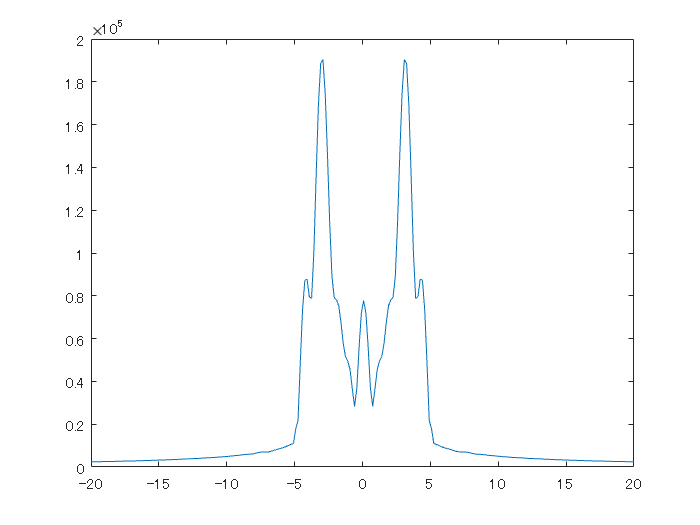

f_LPF = linspace(-Fs/2,Fs/2,numel(t_LPF));
impulse_LPF_fft = fft(impulse_LPF);
plot(f_LPF,abs(fftshift(impulse_LPF_fft)));
xlim([-2/Td 2/Td]);

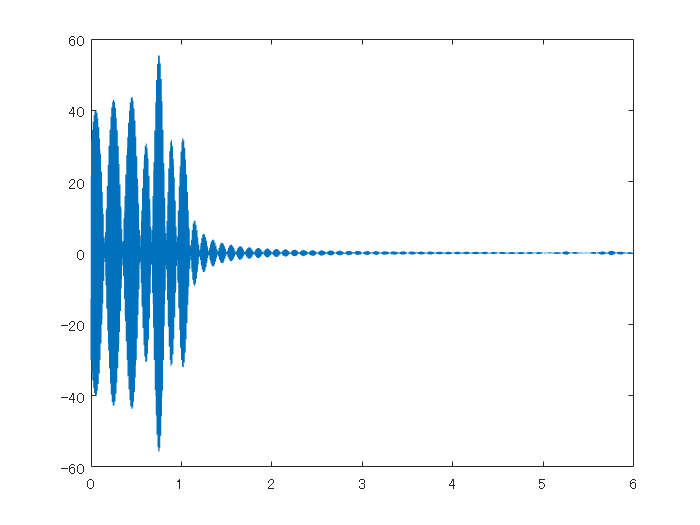


%インパルス列を搬送波に乗せる
carrier = cos(2*pi*Fc*t_LPF); %搬送波
s = impulse_LPF.*carrier;
plot(t_LPF,s);

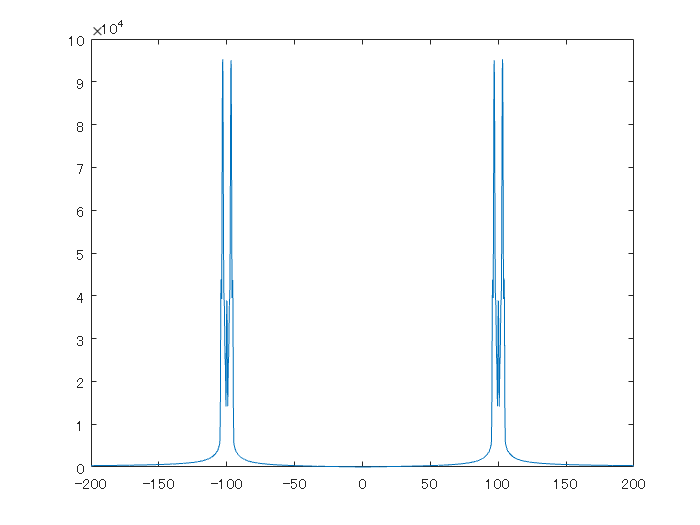

s_fft = fft(s);
plot(f_LPF,abs(fftshift(s_fft)));
xlim([-2*Fc 2*Fc]);

## ノイズ付加

r = s;

## 受信側

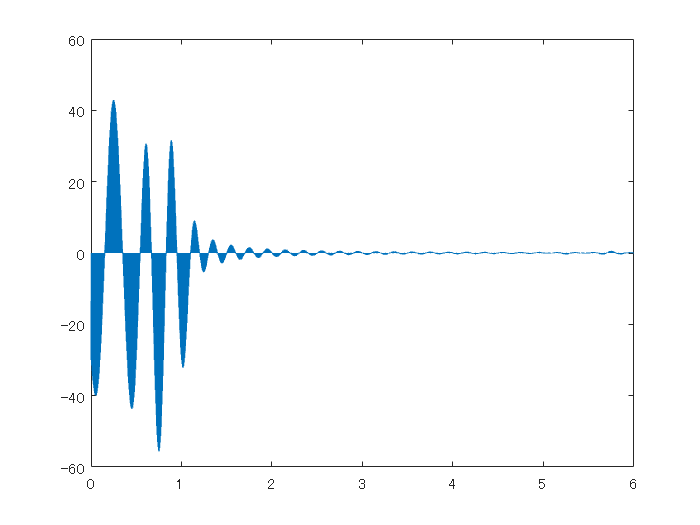

rd = r.*carrier; %受信波と基準信号と掛ける
plot(t_LPF,rd);

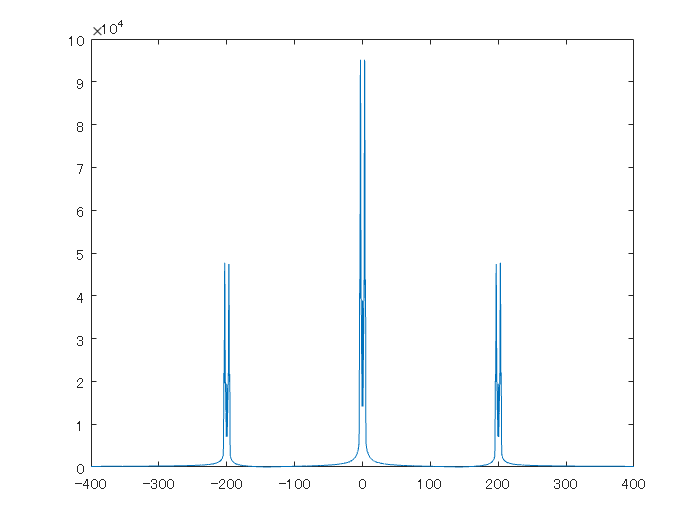

rd_fft = fft(rd);
plot(f_LPF,abs(fftshift(rd_fft)));
xlim([-4*Fc 4*Fc]);

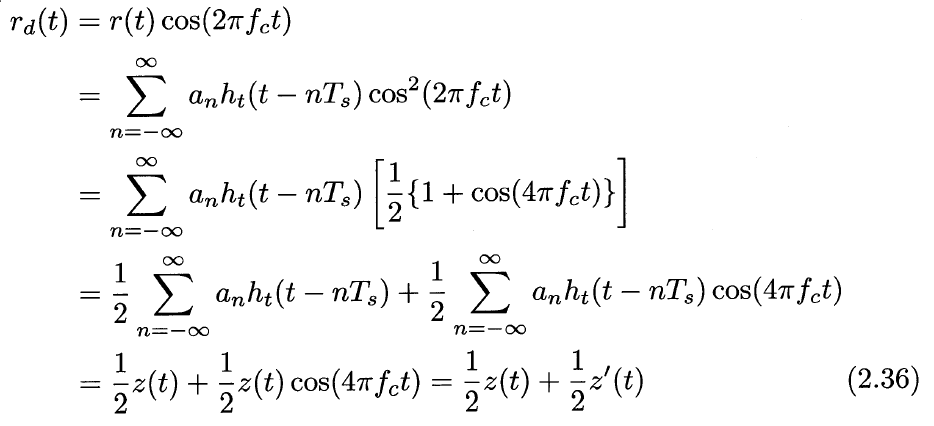

%高調波を除去
%フィルタのインパルス応答を計算（送信側のLPFと同じ）
k = 5%フィルタインパルス応答の打ち切り時間調整

k = 5

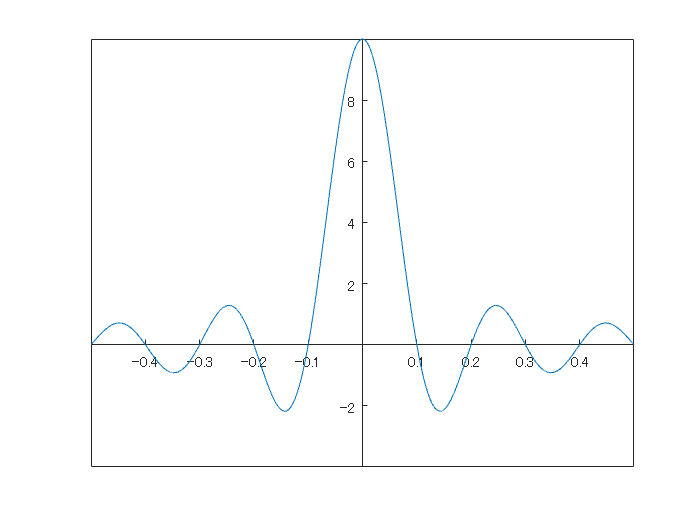

tf = -k*Td:Ts:Td*k-Ts; %フィルタインパルス応答の時間列
h = (1/Td).*sinc(tf/Td);
plot(tf,h);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

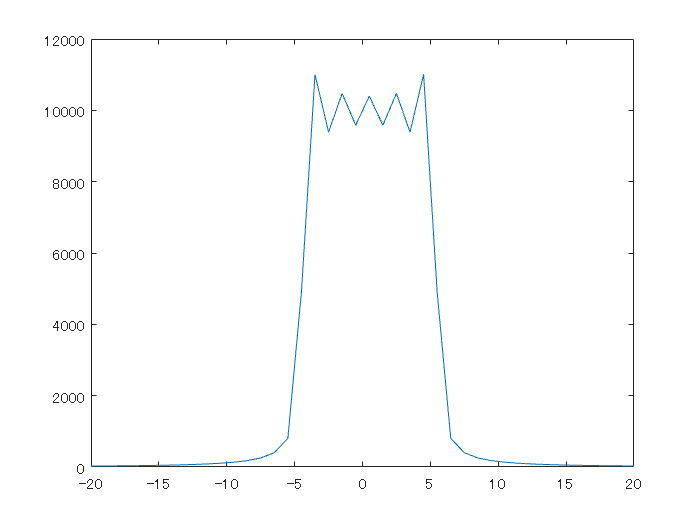

h_fft = fft(h);
f_h = linspace(-Fs/2,Fs/2,numel(tf));
plot(f_h,abs(fftshift(h_fft)));
xlim([-2/Td 2/Td]);

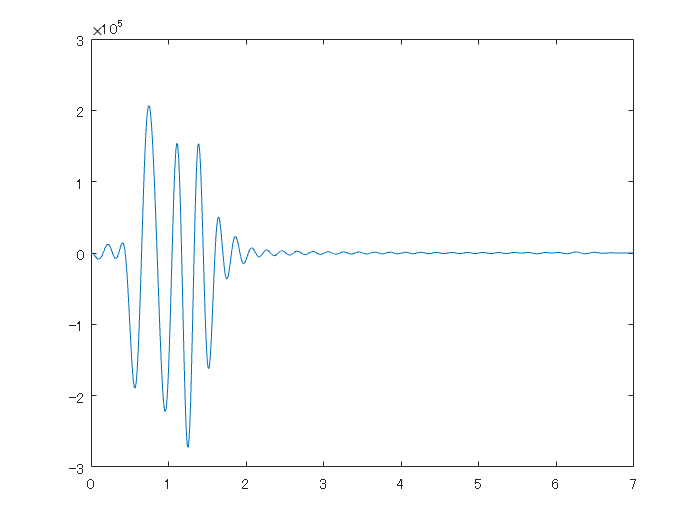


%rdをフィルタに通過させる
rd_LPF = conv(rd,h);
t_LPF = 0:Ts:numel(rd_LPF)*Ts-Ts;
plot(t_LPF,rd_LPF);

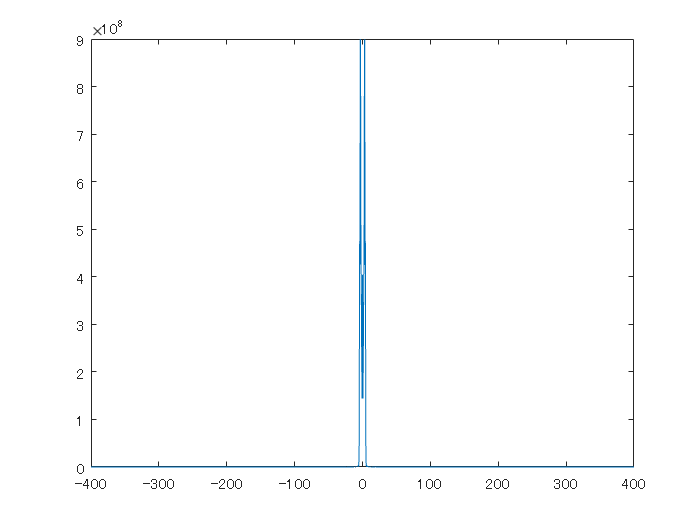

f_LPF = linspace(-Fs/2,Fs/2,numel(t_LPF));
rd_LPF_fft = fft(rd_LPF);
plot(f_LPF,abs(fftshift(rd_LPF_fft)));
xlim([-4*Fc 4*Fc]);